%% EE6641 HW: Linear prediction and time-varying filtering
% Created May 2013.
% Last updated March 15, 2021 for this year's HW3.
% Yi-Wen Liu
clear; close all;
DIR = './HW3-sounds/';
FILENAME = 'a-male-singing.wav';
%FILENAME = 'i-male-singing.wav';
[y,fs1] = audioread([DIR FILENAME]);

%soundsc(y,fs1);
fs = 16000;

y = resample(y,fs,fs1);
%% Parameters to play with
framelen = 0.032; % second. [INVESTIGATE]
p = 20; % linear prediction order. [INVESTIGATE]

%%
L = framelen*fs; %no of samples in a frame

if L<=p
    disp('Linear prediction requires the num of equations to be greater than the number of variables.');
end

numFrames = floor(length(y)/L); % frame rate

excitat = zeros(size(y));
e_n = zeros(p+L,1);


Nfreqs = 2^nextpow2(2*L-1)/2; % Num points for plotting the inverse filter response
df = fs/2/Nfreqs;
ff = 0:df:fs/2-df;

## hyperparameter

sw.emphasis = 1; % default = 1
sw.visOnly = 0; % Visualize the signal only. default = 0.

if sw.emphasis % two tap FIR
    y_emph = filter([1 -0.95],1,y); 
                %[PARAM] -0.95 may be tuned anywhere from 0.9 to 0.99
else
    y_emph = y;
end

%% Linear prediction and smooth synthesis of the estimated source e_n
win = ones(L,1); % Rectangular window.
ext_ind = 1:L+p;
% reference
% win_ola -> overlap 
for kk = 1:numFrames % frame index
    ind = (kk-1)*L+1:kk*L; % pointing to a frame of length L
    ywin = y_emph(ind).*win;
    % ------------------
    A = lpc(ywin,p); %  LPC is the main function to use. Do not change.
    %A = levinson(ywin, p);
    %-------------------
    if sw.visOnly
        excitat(ind) = 0; % Fill an output frame.
    else
        %%% WRITE YOUR CODE HERE and fill excitat(ind) nicely.
        %%% ...
        %e_n = filter([0 -A(2:end)], 1, ywin);
        %e_n = filter(A, [1], ywin(1:L));
        e_n = filter(A(1:end), 1, cat(1, ywin, zeros(p, 1)));
        excitat(ind(1):ind(end-p)) = e_n(p+1:L);
        
        %e = ywin-y_estm;  %% errors
        %gain(kk)=sqrt(sum(e(1:length(e)).^2)/length(e));%%sqrt(MSE)
        
    end
    
    Y = fft(ywin,2*Nfreqs);
%% Data visualization
    figure(1);
    subplot(221);
    plot(ind/fs*1000, y(ind));
    xlabel('ms')
    set(gca,'xlim',[kk-1 kk]*framelen*1000);
    
    subplot(222);
    plot(ind/fs*1000, e_n(p+1:end));
    set(gca,'xlim',[kk-1 kk]*framelen*1000);
   
    subplot(223); % two line
    [H,W] = freqz(1,A,Nfreqs);
    Hmag = 20*log10(abs(H));
    Ymag = 20*log10(abs(Y(1:Nfreqs))); % NEED DEBUG
    Hmax = max(Hmag);
    offset = max(Hmag) - max(Ymag);
    plot(ff,Hmag); hold on;
    plot(ff,Ymag+offset,'r'); hold off;
    set(gca,'xlim',[0 fs/2],'ylim',[Hmax-50, Hmax+5]);
    xlabel('Hz')
    
    subplot(224);
    plot(ff,Ymag+offset-Hmag);
    set(gca,'xlim',[0 fs/2],'ylim',[-30, 25]);
    xlabel('Hz');
    
    drawnow;
    %pause;
end

Result

%% [INVESTIGATE] play the estimated source signal.
% With a proper choice of LP order, frame length, and the pre-emphasis filter coefficient, 
% the sound should lack the original vowel quality in x[n].

%for kk=1:L:numFrames*2
%    w=filter(1,[1 A((kk+1):(kk+1+p-1))],gain(kk));
%    y_hat(kk:kk+L-1) = w; 
%end


soundsc(excitat,fs); 

setFontSizeForAll(18); % This function is a plotting routine I created. 
                        % It goes through all the figures and set the font
                        % the same size.

Overlap the Linear Prediction

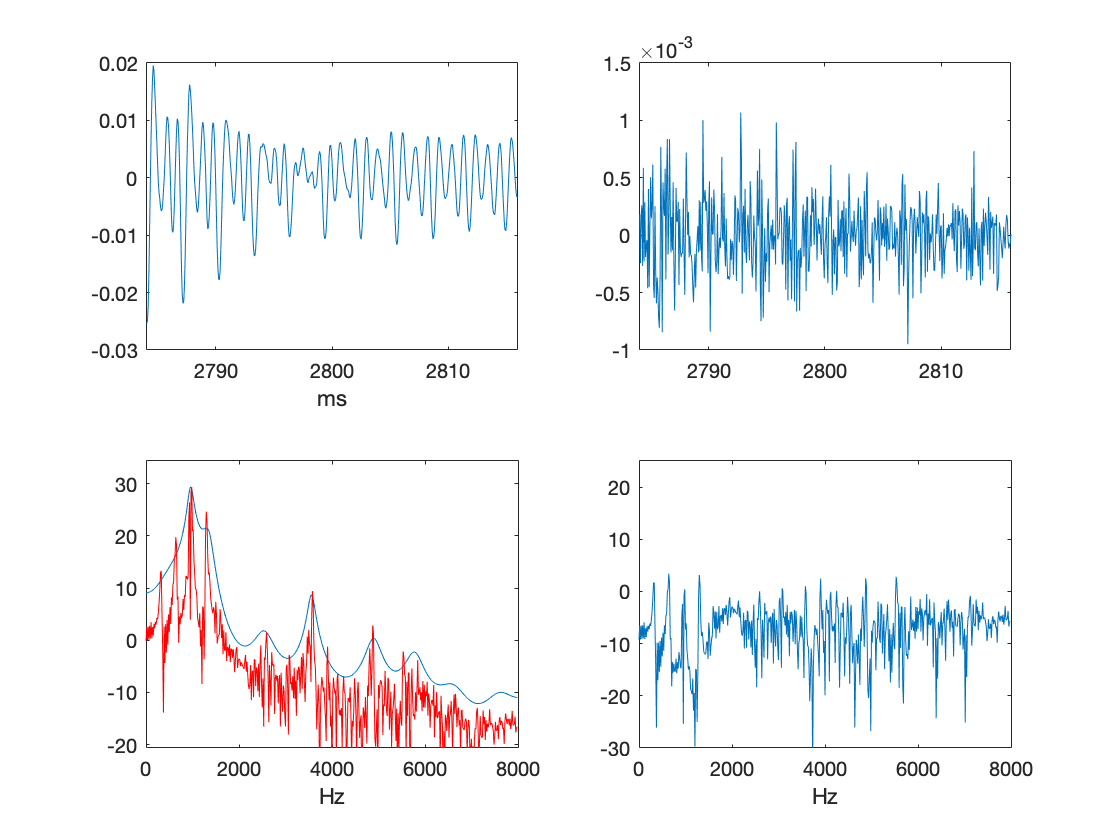

plot(fs, excitat)